# 计算Ground Truth

DirName = './C12Circle';
[FileTable,Nfile] = GetAllFile(DirName,'DAT')

FileTable = 8×1 cell 数组
    {'ReceivedTofile-COM21-2021_8_3_20-11-30.DAT'}
    {'ReceivedTofile-COM21-2021_8_3_20-29-50.DAT'}
    {'ReceivedTofile-COM21-2021_8_3_20-47-04.DAT'}
    {'ReceivedTofile-COM21-2021_8_4_10-43-06.DAT'}
    {'ReceivedTofile-COM21-2021_8_4_10-58-02.DAT'}
    {'ReceivedTofile-COM21-2021_8_4_11-09-23.DAT'}
    {'ReceivedTofile-COM21-2021_8_4_11-25-16.DAT'}
    {'ReceivedTofile-COM21-2021_8_4_11-41-43.DAT'}


Nfile = 8


RawProterty = zeros(Nfile,6);
for i = 1:Nfile
% fileName = 'ReceivedTofile-COM21-2021_8_3_20-11-30.DAT';
fileName = [DirName '/' FileTable{i}];
RTKRawData = ImportGTData(fileName);

## 导入观测数据

data = RTKRawData;
jIndex = {1 2 3 4 5 6 7 8 9 10 11};
[jLat, jLng, jFlag, jAlt] = jIndex{:};

FlagTable = sort(unique(data(:,jFlag)),'descend');

% 0：无定位，1：单点定位，2：差分定位，4：RTK固定，收敛，5：RTK 浮点
if FlagTable(1) == 0
    error('No position')
else
    dataIndex = find(data(:,jFlag) == 4);
    if isempty(dataIndex)
        dataIndex = find(data(:,jFlag) == FlagTable(1));
    end
end
data = data(dataIndex,:);

AverData = mean(data,1);
LLADDD = [floor(AverData(jLat:jLng)/100)+mod(AverData(jLat:jLng),100)/60 AverData(jAlt)];

RawProterty(i,:) =  [LLADDD size(data,1) size(dataIndex,1) size(dataIndex,1)/size(data,1)];
end

% |_________________________________|
% |---------------------------------|_
% |                                 |_·4
% |                                 |
% |                                 |_
% |                                 |_|
% |---------------------------------| .7
% |`````````````````````````````````|



## 原始数据打点

Position = RawProterty(:,1:3)

Position =    30.5114  114.4017   37.8595
   30.5113  114.4018   37.3558
   30.5113  114.4018   37.2874
   30.5113  114.4019   37.1540
   30.5113  114.4015   36.9143
   30.5113  114.4015   37.0022
   30.5114  114.4015   37.1324
   30.5115  114.4019   37.0929


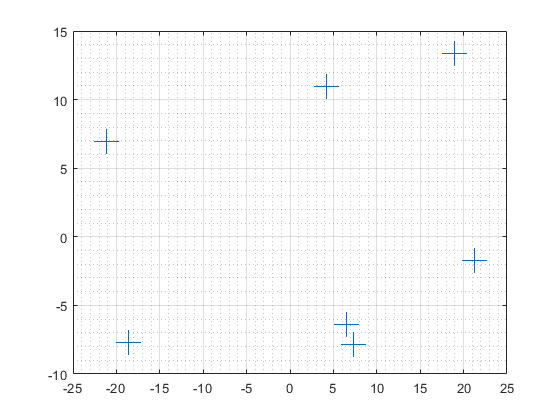

p = [Position(:,2) Position(:,1)]';

llaAver = mean(Position,1);%median position
nedM = Lla2Ned(Position,llaAver);%keep the NaNs in for the plot
%so we see a break in the lines where there was no position
figure
h = plot(nedM(:,2),nedM(:,1),'+','MarkerSize',18);
grid on
grid minor

lat = mean(Position([1 2 6 3 5],1));
lng = mean(Position([4 5 7],2));

Position(1,1) = lat;
Position(2,1) = lat;
Position(3,1) = lat;
Position(5,1) = lat;
Position(6,1) = lat;

Position(4,2) = lng;
Position(5,2) = lng;
Position(7,2) = lng;

llaAver = mean(Position,1);%median position
nedM = Lla2Ned(Position,llaAver);%keep the NaNs in for the plot
%so we see a break in the lines where there was no position
figure
h1 = plot(nedM(:,2),nedM(:,1),'b+','MarkerSize',18);
hold on
w0 = nedM(7,2)-nedM(1,2) + 1

w0 = -9.3725

h0 = nedM(4,1)-nedM(7,1) + 1.5

h0 = -7.1643

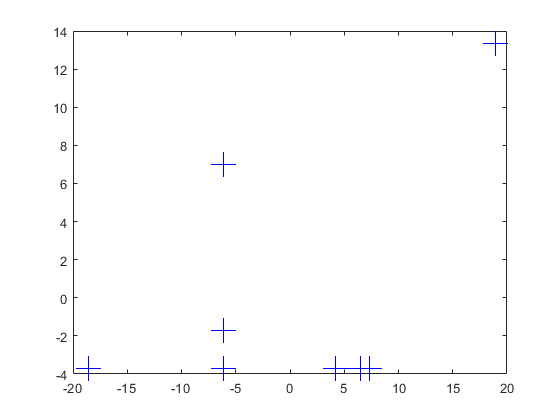

错误使用 rectangle
宽度和高度必须大于或等于 0

x0 = nedM(1,2)-1;
y0 = nedM(7,1);
rectangle('Position',[x0,y0,w0,h0])

w1 = nedM(7,2)-nedM(1,2)
h1 = nedM(4,1)-nedM(7,1)
x1 = nedM(1,2);
y1 = nedM(7,1);
rectangle('Position',[x1,y1,w1,h1],'EdgeColor','r')
grid on
grid minor
hold off

% |---------------------------------|
% |  ·             ·             ·  |
% |                                 |
% |  ·             ·             ·  |
% |                                 |
% |  ·             ·             ·  |
% |---------------------------------|


llaA =  [Position(7,1) Position(1,2)];
llaB =  [Position(4,1) Position(4,2)];
llaC =  [Position(7,1) Position(4,2)];
llaTag = mean(Position([2 6],:),1)

%    B
% A  C
iA = 1;iB = 2; iC = 3;
Altitude = 37.1711806451613;
Beacon = [
    llaA;
    llaB;
    llaC
];
Beacon = [Beacon ones(3,1)*Altitude]

Wid = 14 ;
High = 10;

Nx = 3; Ny = 3;
Testpoint_x = [2 9 14]; % 0.7 = 0.5 + 0.2
Testpoint_y = (1:4.5:High);

dx = (Beacon(iC, 1:2) - Beacon(iA, 1:2)) ./ Wid;
dy = (Beacon(iB, 1:2) - Beacon(iC, 1:2)) ./ High;

point_x = ones(Ny, Nx);
point_y = ones(Ny, Nx);

for j=1:Nx
    for i=1:Ny
        position = Testpoint_x(j) * dx + Testpoint_y(i) * dy;
        point_x(i,j) = position(2);
        point_y(i,j) = position(1);        
    end
end

figure
plot(point_x(1,:), point_y(1,:));
figure
plot(point_x, point_y,'+');

posx = Beacon(iA,2) + point_x;
posy = Beacon(iA,1) + point_y;

% pos
% x/y =
% 1   6   11 ...
% 2   7   12 ...
% 3   8   13 ...
% 4   9   14 ...
% 5   10  15 ...

% postionAll = [(1:Nx*Ny)'  posy(:) posx(:)];
postionAll = [(1:Nx*Ny)' posy(:) posx(:) ones(Nx*Ny, 1)*Altitude];
DirName = './C12ES';
dlmwrite([DirName '/' 'groundTruth.txt'],postionAll,'delimiter','\t','precision', 16,'newline','pc');



% figure
% plot(postionAll(:,2),postionAll(:,3),'+')
figure
plot(posx,posy,'+')
hold on
plot(Beacon(iA,2), Beacon(iA,1),'+k','MarkerSize',18);
hold on
plot(Beacon(iB,2), Beacon(iB,1),'+k','MarkerSize',18);
hold on
plot(Beacon(iC,2), Beacon(iC,1),'+k','MarkerSize',18);
hold on
plot(Beacon([iA iC],2), Beacon([iA iC],1))
hold on
plot(Beacon([iC iB],2), Beacon([iC iB],1))